## PMDC Motor without any controller

This section shows the simulation of the PMDC Motor without any controller.

The differential equation of the Permanent Magnet DC motor can be written in $\dot{X}=AX+BU$ form as follows


$$\pmatrix{\frac{di_a}{dt} \cr \frac{dw}{dt} }=\pmatrix{\frac{-Ra}{La} & \frac{-k_b}{La}  \cr \frac{k_t}{J}  & \frac{-B}{J}}\pmatrix{i_a \cr w}+\pmatrix{\frac{1}{L_a} & 0 \cr 0& \frac{-1}{J}}\pmatrix{V_{input} \cr T_{load}}$$
 

If the speed of the motor is considered as output then $Y=CX+DU$can be given as 

$w=\pmatrix{0 & 1}\pmatrix{ia \cr w}+\pmatrix{0 & 0}\pmatrix{V_{input} \cr T_{load}}$.

clc;
clear;
close all;
La=0.01;
Ra=0.1;
J=10;
B=0.01;
kb=1;
kt=1;
tspan=[0,90];
x0=[0,0];
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B/J)];
global B

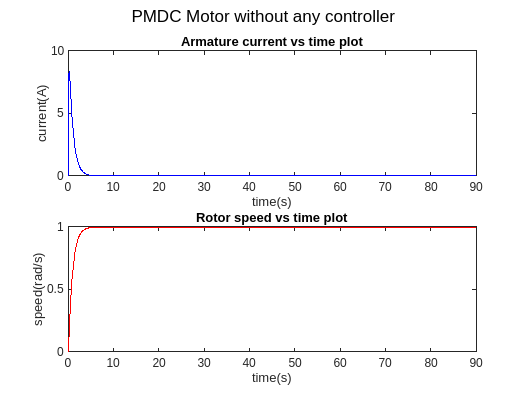

B=[1/La 0;0 -1/J];
V_input=1;
T_load=0;
[t,x]=ode45(@(t,x) PMDC(t,x,V_input,T_load),tspan,x0);
figure
hold on
sgtitle('PMDC Motor without any controller')
subplot(2,1,1)
plot(t,x(:,1),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(:,2),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

## **Feed-forward Controller or Open Loop Controller for PMDC Motor**

One can also have the system equation of the PMDC Motor as


$$\pmatrix{\frac{di_a}{dt} \cr \frac{dw}{dt} \cr \frac{d\theta}{dt} }=\pmatrix{\frac{-Ra}{La} & \frac{-k_b}{La}  & 0\cr \frac{k_t}{J}  & \frac{-B}{J} & 0 \cr 0 & 1 & 0}\pmatrix{i_a \cr w \cr \theta}+\pmatrix{\frac{1}{L_a} & 0 \cr 0 & \frac{-1}{J} \cr 0 & 0}\pmatrix{V_{input}}$$


$\theta=\pmatrix{0 & 0 &1}\pmatrix{ia \cr w \cr \theta}+\pmatrix{0 & 0}\pmatrix{V_{input} \cr T_{load}}$.

Setting $$T_{load}$$=0 Nm

$\pmatrix{\frac{di_a}{dt} \cr \frac{dw}{dt} \cr \frac{d\theta}{dt} }=\pmatrix{\frac{-Ra}{La} & \frac{-k_b}{La}  & 0\cr \frac{k_t}{J}  & \frac{-B}{J} & 0 \cr 0 & 1 & 0}\pmatrix{i_a \cr w \cr \theta}+\pmatrix{\frac{1}{L_a} \cr 0 \cr 0}\pmatrix{V_{input}}$ and $\theta=\pmatrix{0 & 0 &1}\pmatrix{ia \cr w \cr \theta}+\pmatrix{0 }\pmatrix{V_{input}}$

The transfer function $\frac{\theta(s)}{V_{input}(s)} $ is obtained by setting the other input $T_{load}=0Nm$.

The transfer function for this system is given by $\frac{\theta(s)}{V_{input}(s)}=\frac{\frac{k_t}{L_aJ}}{s(s^2+\frac{R_a}{L_a}s+\frac{B}{J}s+\frac{R_aB}{L_aJ}+\frac{k_tk_b}{L_aJ})}$.

This is a Type-1 system.

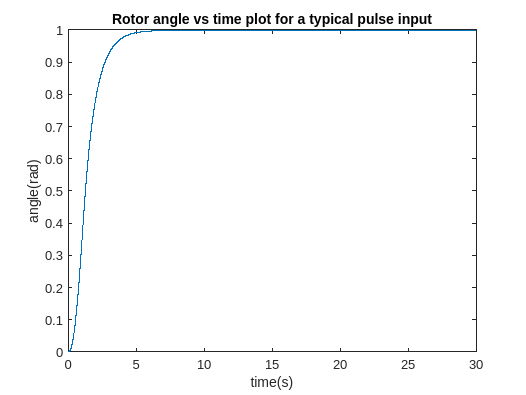

clc;
clear;
close all;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
w_inf=20;
K_ff=10.01*w_inf/10;
tspan=[0,90];
x0=[0,0];
global A
A=[-(Ra/La) -(kb/La) 0;(kt/J) (-B_w/J) 0;0 1 0];
global B
B=[1/La ;0;0];
C=[0,0,1];
D=[0];
[num,den]=ss2tf(A,B,C,D);
P=tf(num,den);
P_delay=tf(num,den,'InputDelay',1);
t=0:1e-3:30;
y1=step(P,t,'r');
y2=step(P_delay,t,'b');
y=y1-y2;
plot(t,y)
hold on
xlabel('time(s)')
ylabel('angle(rad)')
title('Rotor angle vs time plot for a typical pulse input')
hold off

**To find:- **the DC gainBy Final value theorem,


$$\lim_{t \to \infty} \theta(t)=\lim_{s \to 0} {s\theta(s)}=\lim_{s \to 0} {s(\theta_1(s)-\theta_2(s))}=\lim_{s \to 0} s(\frac{\frac{k_t}{L_aJ}}{s(s^2+\frac{R_a}{L_a}s+\frac{B}{J}s+\frac{R_aB}{L_aJ}+\frac{k_tk_b}{L_aJ})}.\frac{1}{s}-\frac{\frac{k_t}{L_aJ}}{s(s^2+\frac{R_a}{L_a}s+\frac{B}{J}s+\frac{R_aB}{L_aJ}+\frac{k_tk_b}{L_aJ})}.\frac{e^{-s}}{s}$$


**FUNCTION DECLARATIONS**

function dx=PMDC(t,x,vol_input,load_torque)
dx=zeros(2,1);
if (t>45 && t<100)
    torque_input=load_torque*1;
else
    torque_input=0;
end
if vol_input==0
global tp ep
theta_ref=0.1;
e=theta_ref-x(3);
de=-x(2);
Vinput=control(t,e,de,tp);
tp=t;
ep=e;
else
    Vinput=vol_input;
end
u=[Vinput;torque_input];
global A 
global B
dx=A*x+B*u;
end

function u=control(t,e,de,tp)
kp=10;
ki=5;
kd=1;
global I;
I=(I+ki*e*(t-tp));
u=kp*e+I+kd*de;
end

